## **LAB06 - Syed Sualeh Abbas10303**

### **TASK 01:**

**a) How did you find the data?**

To obtain the yearly sunspot data from **1700–2025**, I searched for an authentic and research-based source that provides long-term solar observations. I found the dataset from the official sunspot database maintained by the **Royal Observatory of Belgium** (SILSO). This source is widely used in the scientific community and provides accurate historical records of sunspot numbers in yearly form.

**b) How was it downloaded?**

The dataset was **directly downloaded as a **`.csv`** file** from the SILSO website.

After locating the yearly sunspot data file, I simply downloaded it and saved it in my MATLAB working directory so it could be accessed without any path issues.

**c) How did you convert the data to **`.mat`** and **`.csv`** format?**

Since the file was already in `.csv` format, it was first imported into MATLAB and then saved as a `.mat` file.

**Steps performed in MATLAB:**

- **Read the CSV file:**

`data = readtable('sunspot_data.csv');`

- **Store required columns (year and sunspot number) into variables:**

`year = data.Year;`

`sunspot_number = data.SunspotNumber;`

- **Save the data as a **`.mat`** file:**

`save('sunspot_data.mat','year','sunspot_number');`

The `.mat` file allows faster loading and keeps the variables in MATLAB format for further signal processing.

**d) Folder creation and submission**

At the end of the lab:

- A folder was created with LAB Number.

- The following files were placed inside it:

- MATLAB script / live script (`.m` or `.mlx`)

- Sunspot dataset in `.csv` format (original downloaded file)

- Converted `.mat` file

- This organized folder was prepared for submission as required

clc;
clear;
close all;

%% Step 1: Select and read the CSV file
data = readtable('C:\Users\Administrator\OneDrive - Habib University\Sem 4\Signals & Systems\MatLab\lab06\SN_y_tot_V2.0.csv'); 

%% Step 2: Display first few rows to verify
disp(head(data));

     Var1     Var2    Var3    Var4    Var5
    ______    ____    ____    ____    ____

    1700.5     8.3     -1      -1      1  
    1701.5    18.3     -1      -1      1  
    1702.5    26.7     -1      -1      1  
    1703.5    38.3     -1      -1      1  
    1704.5      60     -1      -1      1  
    1705.5    96.7     -1      -1      1  
    1706.5    48.3     -1      -1      1  
    1707.5    33.3     -1      -1      1  



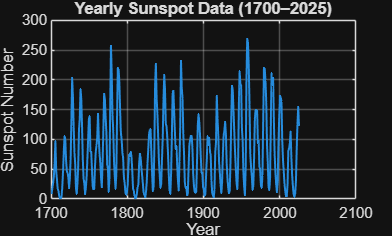


%% Step 3: Extract required columns
% (Update column names according to your CSV file)

year = data{:,1};              % first column → Year
sunspot_number = data{:,2};   % second column → Sunspot values

%% Step 4: Plot the data (for verification)
figure;
plot(year, sunspot_number, 'LineWidth', 1.2);
xlabel('Year');
ylabel('Sunspot Number');
title('Yearly Sunspot Data (1700–2025)');
grid on;


%% Step 5: Save as MAT file
save('sunspot_data.mat', 'year', 'sunspot_number');

%% Step 6: (Optional) Write a clean CSV from MATLAB
sunspot_table = table(year, sunspot_number);
writetable(sunspot_table, 'sunspot_data_converted.csv');

%% Step 7: Confirmation message
disp('Sunspot data successfully imported and saved as .mat and .csv');

Sunspot data successfully imported and saved as .mat and .csv


### TASK 2:

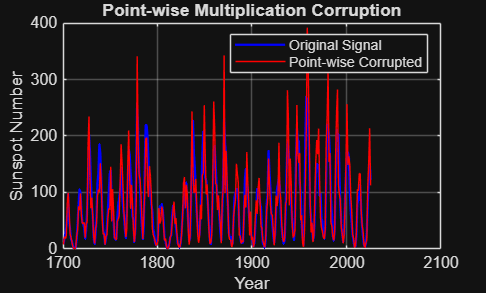

clc;
clear;
close all;

%% ===================== Load Sunspot Data =====================
% Make sure sunspot_data.mat contains:
% year  -> Nx1
% sunspot_number -> Nx1

load('sunspot_data.mat');

x = sunspot_number(:);     % Original signal (column vector)
t = year(:);
N = length(x);

%% ============================================================
%% Part (a) Point-wise multiplication with vector V
%% ============================================================

% Create random vector V (same length as signal)
V = 0.5 + rand(N,1);    % values between 0.5 and 1.5

% Corrupt the signal
x_point_corrupt = x .* V;

% Plot
figure;
plot(t, x, 'b', 'LineWidth', 1.4); hold on;
plot(t, x_point_corrupt, 'r');
legend('Original Signal','Point-wise Corrupted');
xlabel('Year');
ylabel('Sunspot Number');
title('Point-wise Multiplication Corruption');
grid on;

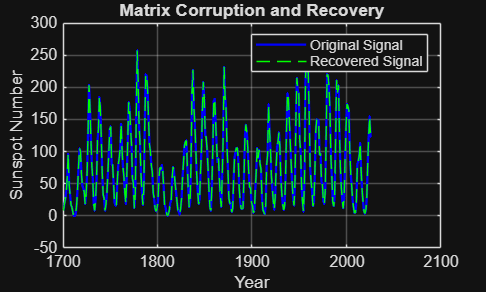


% Recovery (since V is known and non-zero)
x_point_recovered = x_point_corrupt ./ V;


%% ============================================================
%% Part (b) Matrix multiplication corruption and recovery
%% ============================================================

% Create a random invertible square matrix
M = rand(N);

% Make sure matrix is invertible
while det(M) == 0
    M = rand(N);
end

% Corrupt the signal
y_matrix = M * x;

% Recover the original signal
x_matrix_recovered = inv(M) * y_matrix;

% Plot comparison
figure;
plot(t, x, 'b', 'LineWidth', 1.4); hold on;
plot(t, x_matrix_recovered, '--g');
legend('Original Signal','Recovered Signal');
xlabel('Year');
ylabel('Sunspot Number');
title('Matrix Corruption and Recovery');
grid on;

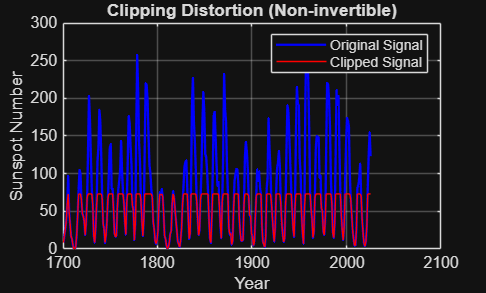



%% ============================================================
%% Part (c) Clipping (Non-invertible distortion)
%% ============================================================

clip_level = 73;   % 70 + last digit of ID (10303)

x_clipped = x;

% Apply clipping
x_clipped(x > clip_level) = clip_level;

% Plot clipped signal
figure;
plot(t, x, 'b', 'LineWidth', 1.4); hold on;
plot(t, x_clipped, 'r');
legend('Original Signal','Clipped Signal');
xlabel('Year');
ylabel('Sunspot Number');
title('Clipping Distortion (Non-invertible)');
grid on;

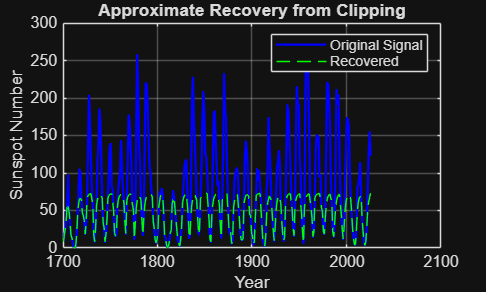



%% -------- Approximate Recovery using Interpolation --------
x_recovered_clip = x_clipped;

for k = 2:N-1
    if x_clipped(k) == clip_level
        % Replace clipped sample using neighboring values
        x_recovered_clip(k) = (x_recovered_clip(k-1) + x_recovered_clip(k+1)) / 2;
    end
end

% Plot recovered clipped signal
figure;
plot(t, x, 'b', 'LineWidth', 1.4); hold on;
plot(t, x_recovered_clip, '--g');
%As all of the information above 73 is lost, so we cannot recover that
%because its a non invertable matrix.
legend('Original Signal','Recovered');
xlabel('Year');
ylabel('Sunspot Number');
title('Approximate Recovery from Clipping');
grid on;



%% ============================================================
%% Error Power Calculation (for comparison)
%% ============================================================

error_matrix = x - x_matrix_recovered;
error_clip = x - x_recovered_clip;

P_matrix = 10*log10(sum(error_matrix.^2));
P_clip = 10*log10(sum(error_clip.^2));

disp(['Error Power (Matrix Recovery; part B) = ', num2str(P_matrix), ' dB']);

Error Power (Matrix Recovery; part B) = -183.4456 dB


disp(['Error Power (Clipping Recovery; part C) = ', num2str(P_clip), ' dB']);

Error Power (Clipping Recovery; part C) = 59.8905 dB


### **TASK 3: **

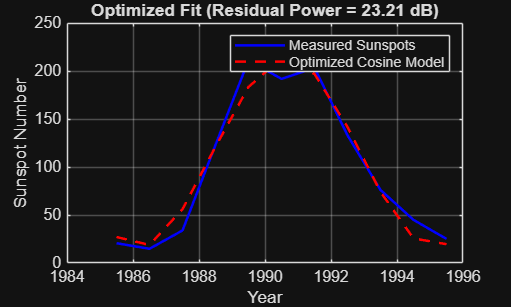

clc; clear; close all;

%% ================== Load Sunspot Data ==================
load('sunspot_data.mat');

%% ================== Extract July 1985 – June 1996 ==================
% We extract only the required cycle from July 1985 to June 1996

start_year = 1985;
end_year   = 1996;
idx = (year >= start_year & year < end_year);
t_cycle = year(idx);
x_cycle = sunspot_number(idx);

%% ================== Define Cosine Model ==================
% Model form:
% x(t) = a - b*cos(c*(t - d))
% a -> vertical shift
% b -> amplitude
% c -> frequency
% d -> phase shift

%% ================== Initial Guess ==================
% We provide reasonable physical guesses:
% - Mean value as vertical shift
% - Half peak-to-peak as amplitude
% - 11 year solar cycle frequency
% - Starting year as phase shift

a0 = mean(x_cycle);
b0 = (max(x_cycle) - min(x_cycle)) / 2;
c0 = 2*pi/11;      % known solar cycle approx 11 years
d0 = 1985;

params0 = [a0 b0 c0 d0];

%% ================== Parameter Optimization ==================
% We minimize residual power automatically using fminsearch
% This finds the best fitting parameters

objective = @(p) mean((x_cycle - (p(1) - p(2)*cos(p(3)*(t_cycle - p(4))))).^2);

best_params = fminsearch(objective, params0);

a = best_params(1);
b = best_params(2);
c = best_params(3);
d = best_params(4);

%% ================== Generate Best Model ==================
x_model = a - b*cos(c*(t_cycle - d));

%% ================== Compute Residuals and Power ==================
[resPower_dB, residuals] = computeResidualPower(a,b,c,d,t_cycle,x_cycle);

%% ================== Compute Signal Power and SNR ==================
signalPower = mean(x_cycle.^2);
residualPower = mean(residuals.^2);
SNR_dB = 10*log10(signalPower / residualPower);

%% ================== Plot Data and Model ==================
figure;
plot(t_cycle, x_cycle, 'b','LineWidth',1.5); 
hold on;
plot(t_cycle, x_model, 'r--','LineWidth',1.5);
legend('Measured Sunspots','Optimized Cosine Model');
xlabel('Year');
ylabel('Sunspot Number');
title(['Optimized Fit (Residual Power = ', num2str(resPower_dB,'%.2f'),' dB)']);
grid on;

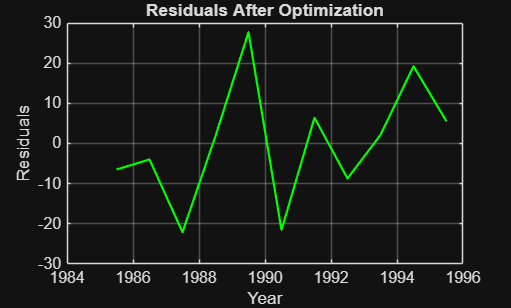


%% ================== Plot Residuals ==================
figure;
plot(t_cycle, residuals,'g','LineWidth',1.3);
xlabel('Year');
ylabel('Residuals');
title('Residuals After Optimization');
grid on;


%% ================== Display Results ==================
disp('Optimized Parameters:');

Optimized Parameters:


disp(['a = ', num2str(a)]);

a = 115.0726


disp(['b = ', num2str(b)]);

b = 98.8526


disp(['c = ', num2str(c)]);

c = 0.7018


disp(['d = ', num2str(d)]);

d = 2066.7509


disp(['Residual Power = ', num2str(resPower_dB,'%.2f'),' dB']);

Residual Power = 23.21 dB


disp(['Signal-to-Noise Ratio = ', num2str(SNR_dB,'%.2f'),' dB']);

Signal-to-Noise Ratio = 18.57 dB



function [resPower_dB, residuals] = computeResidualPower(a,b,c,d,t,x)

% This function computes:
% 1) Residuals between measured data and model
% 2) Residual power in dB
% Residual = Measured - Model
% Residual Power = mean(residual^2)
% Converted to dB scale

x_model = a - b*cos(c*(t - d));
residuals = x - x_model;
resPower = mean(residuals.^2);
resPower_dB = 10*log10(resPower);
end


In this task, the July 1985 to June 1996 sunspot cycle was modeled using the cosine function x(t)=a−bcos (c(t−d)). Since solar activity follows an approximately 11-year periodic cycle, a cosine model is appropriate because it captures the oscillatory nature of the data. To determine the best-fitting parameters, a nonlinear least squares approach was used. Initial parameter estimates were chosen based on physical intuition: the mean of the data was used for the vertical shift, half the peak-to-peak value for the amplitude, 2π/11 for the frequency (based on the known solar cycle period), and the starting year for the phase shift. MATLAB’s `fminsearch` function was then used to minimize the mean squared error between the measured sunspot data and the model. This optimization adjusts the parameters a,b,c and d automatically to obtain the best fit

The goodness of fit was evaluated using residual analysis. The residuals were computed as the difference between the measured data and the model output. The residual power was calculated as the mean squared value of the residuals and expressed in decibels (dB) using 10log (mean(residual2)). Residual power quantifies the average energy of the modeling error; therefore, a lower residual power indicates a better fit. Additionally, the Signal-to-Noise Ratio (SNR) was computed by comparing the signal power to the residual power. A higher SNR indicates that the model explains a larger portion of the signal’s energy, which confirms a stronger goodness of fit. Overall, the nonlinear least squares cosine model effectively captures the periodic behavior of the sunspot cycle and provides a quantitative measure of fitting accuracy through residual power and SNR.